y = abs(fft(myRecording))

y =     1.1953
    0.6046
    0.1925
    1.0620
    0.5458
    0.4780
    0.8468
    0.5068
    0.5821
    0.2112


y = 20*log10(y);
Fs = 50;
f = (0:length(y)-1)*Fs/length(y);
% [yupper,ylower] = envelope(y) 
% plot(yupper)
% hold on
% plot(ylower)
yy = hilbert(y)

yy =    1.5496 - 0.0000i
  -4.3700 + 7.9974i
 -14.3109 - 1.5315i
   0.5226 - 6.1446i
  -5.2594 + 6.3690i
  -6.4106 - 4.3813i
  -1.4448 + 3.6490i
  -5.9029 + 0.6349i
  -4.7004 + 7.0100i
 -13.5081 - 1.5132i


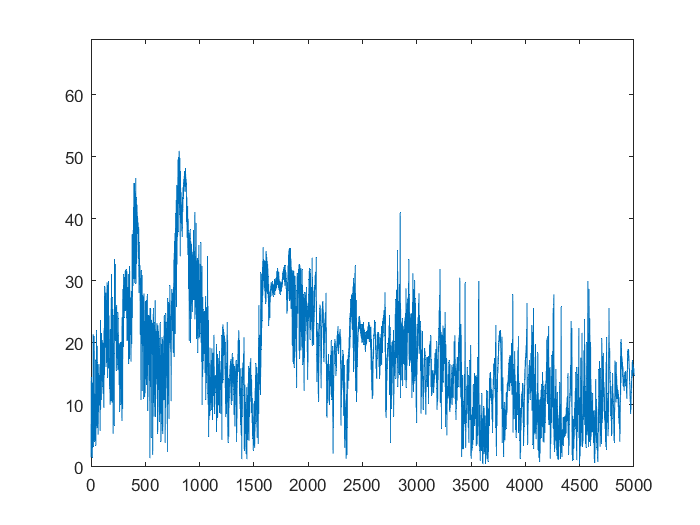

plot(abs(yy))
axis([0 5000 0 69])

%一次只能录一个元音进行分析